# Drinking container classifier

*If you want to try out the classifier immediately, please run this section.*

load('matlab.mat');

## Data Preparation

### Obtaining the datasets

The images datasets were obtained by downloading images from [Google.com](http://google.com) sorted according to respective classes. By using Chrome extension called Image Downloader, multiple images can be downloaded at once. Here is the total images for each class.

Path = fullfile("drink/");
data = imageDatastore(Path,IncludeSubfolders=true,LabelSource="foldernames");

data.countEachLabel

ans = 4×2 table
      Label      Count
    _________    _____

    bottle        76  
    can           73  
    cup           76  
    drink box     74  


### Data augmentation

Since the dataset collected is in small size, data augmentation can be done to increase the number of images.

Rotating, scaling and reflecting the images will increases the dataset three times.

Path = fullfile("containerx3/");
imds = imageDatastore(Path,IncludeSubfolders=true,LabelSource="foldernames");

imds.countEachLabel

ans = 4×2 table
      Label      Count
    _________    _____

    bottle        304 
    can           292 
    cup           304 
    drink box     296 


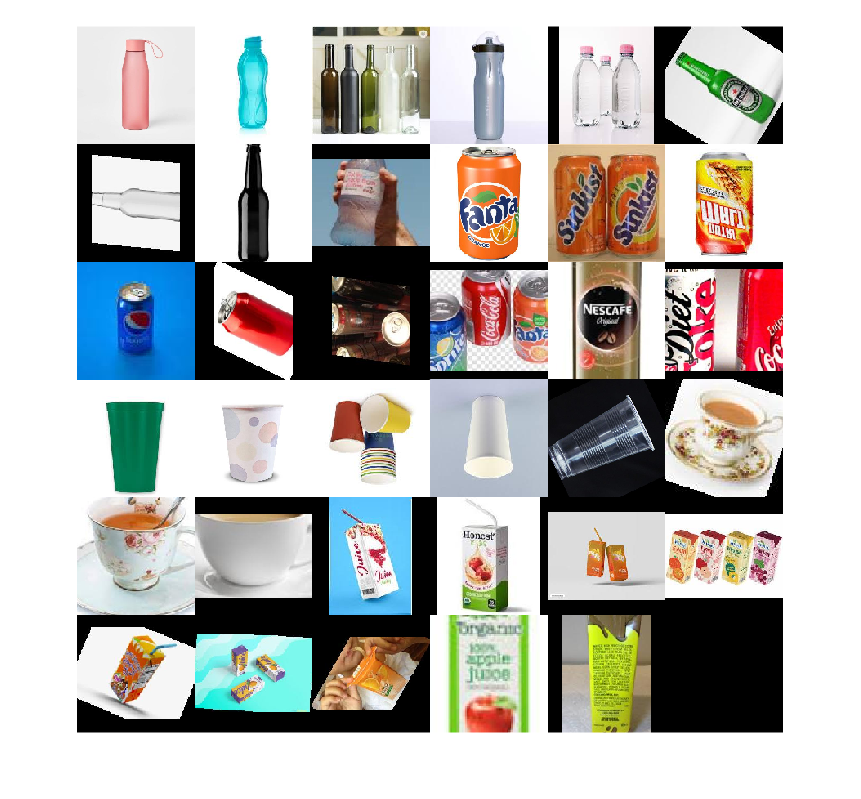

figure
montage(imds.Files(1:35:end))

### Splitting the data

The dataset is splitted into two for training and testing. The training data will have 200 images for each classes, ensuring that the network is trained with the same amount of images.

[imdsTrain,imdsValidation] = splitEachLabel(imds,200,'randomized');

imdsTrain.countEachLabel

ans = 4×2 table
      Label      Count
    _________    _____

    bottle        200 
    can           200 
    cup           200 
    drink box     200 


imdsValidation.countEachLabel

ans = 4×2 table
      Label      Count
    _________    _____

    bottle        104 
    can            92 
    cup           104 
    drink box      96 


## Image Classification

### Load the network and modify the layers

By using a pretrained network GoogLeNet, we can modify the final layers so it can work with the data. Modifying the layers is called 'Transfer Learning'.

net = googlenet;

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

lgraph = layerGraph(net);

numClasses = numel(categories(imdsTrain.Labels));

newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);

lgraph = replaceLayer(lgraph,'loss3-classifier',newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

After modifying the layer, we set the training options with max epoch of 6 and learning rate is 0.0003.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Plots','training-progress');

### Network Training

Let's train the network.

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |       20.00% |       3.4109 |          0.0003 |
|       1 |          50 |       00:01:56 |       90.00% |       0.2409 |          0.0003 |
|       2 |         100 |       00:03:48 |       90.00% |       0.0825 |          0.0003 |
|       2 |         150 |       00:05:49 |       80.00% |       0.3726 |          0.0003 |
|       3 |         200 |       00:07:41 |      100.00% |       0.0160 |          0.0003 |
|       4 |         250 |       00:09:31 |      100.00% |       0.0023 |          0.0003 |
|       4 |         300 |  

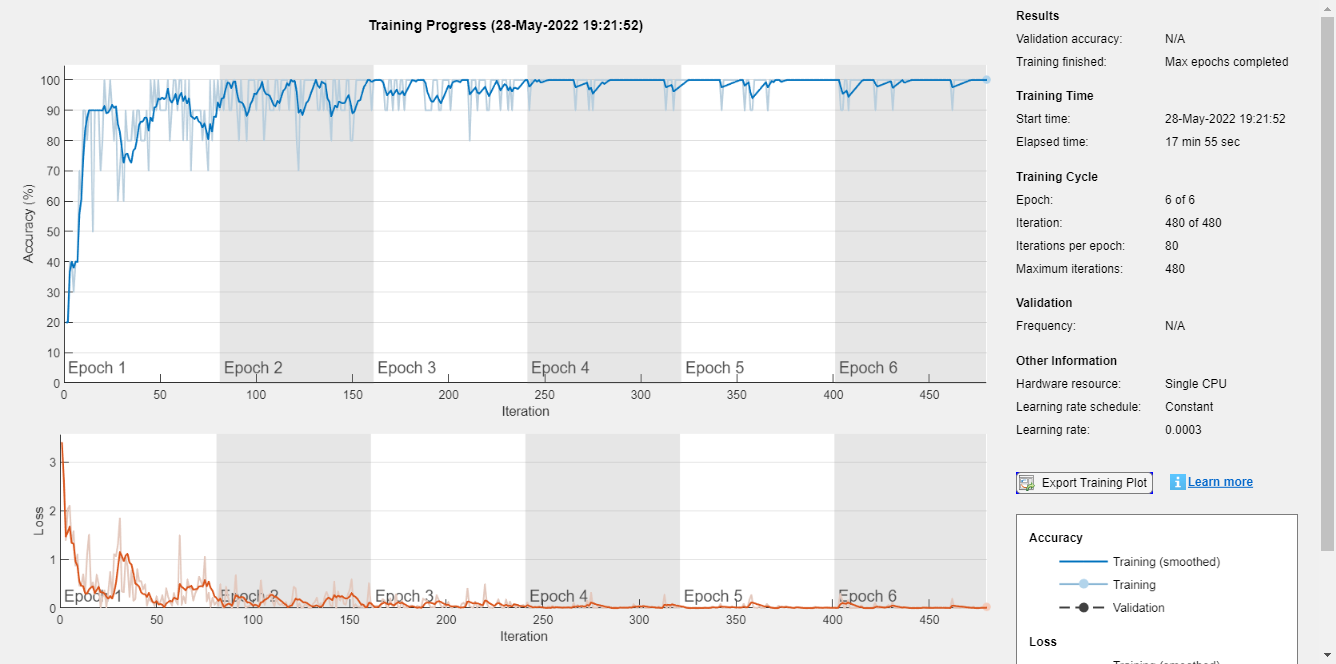

newNet = trainNetwork(augimdsTrain,lgraph,options);

## Testing the Network

After data training, we test the network with the testing data to see how accurate the classifier

[YPred,probs] = classify(newNet,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels);
accuracy

accuracy = 0.9520

Print out the confusion matrix to see how accurate the classifier for each class.

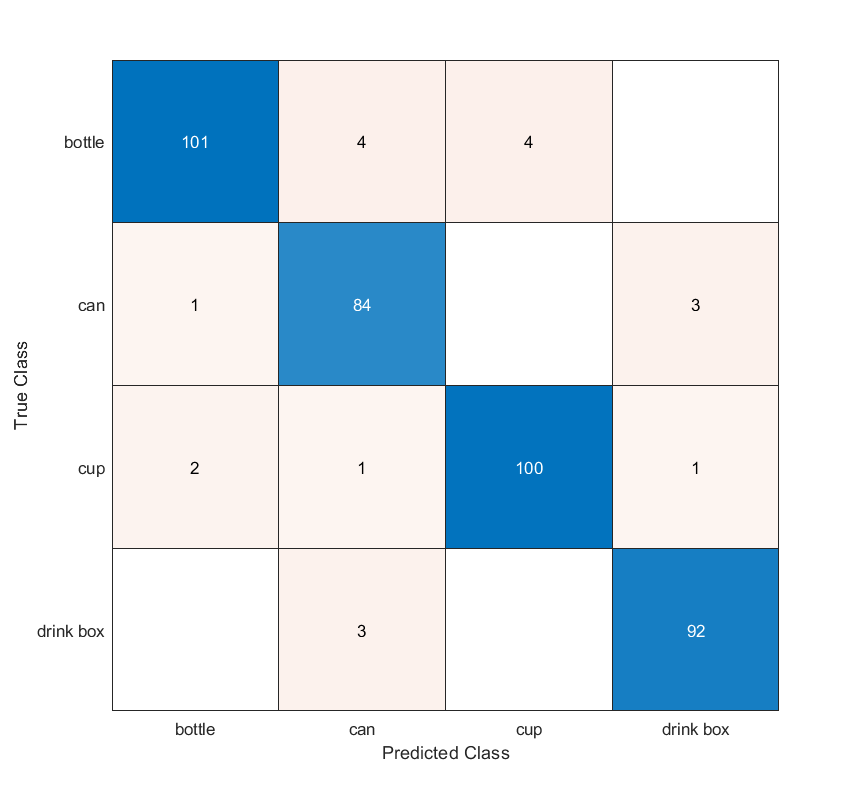

result =   ConfusionMatrixChart with properties:

    NormalizedValues: [4×4 double]
         ClassLabels: [4×1 categorical]

  Show all properties


confMat = confusionmat(YPred,imdsValidation.Labels);
label = unique(imdsValidation.Labels);
result = confusionchart(confMat,label)

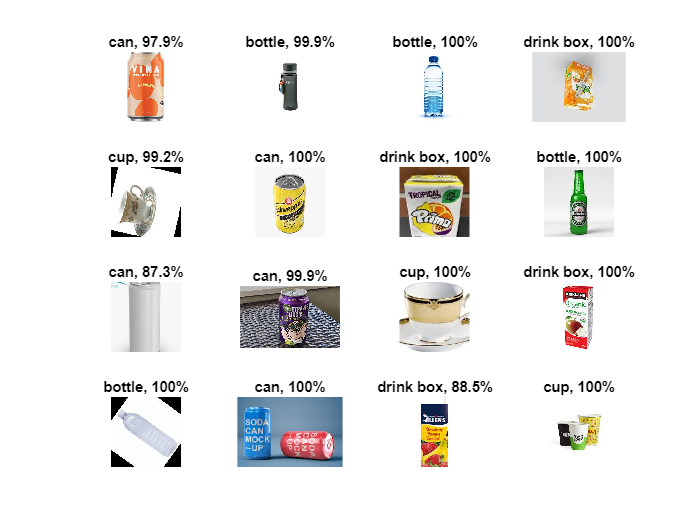

idx = randperm(numel(imdsValidation.Files),16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end

## Try it out with your own image!

Insert your image in **guess** and run the section.

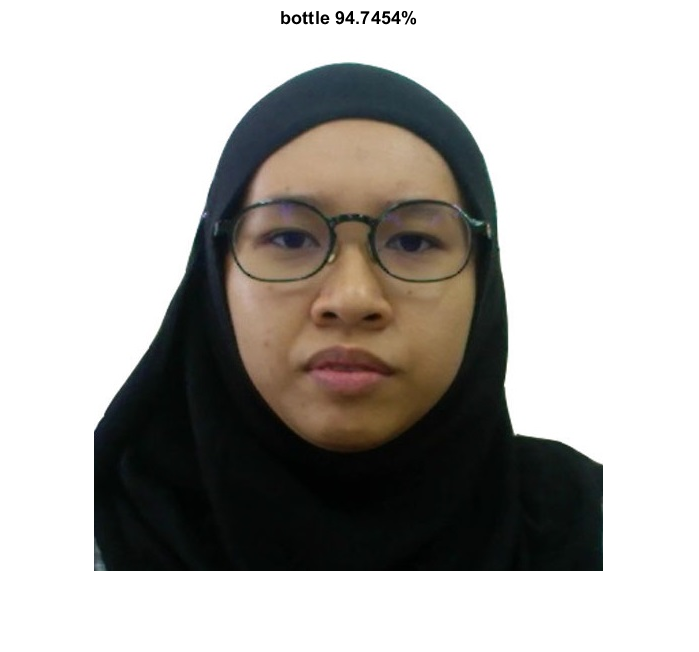

guess=imread("NursaraAin.jpg");
adjust=augmentedImageDatastore(inputSize(1:2),guess);

[i,score]=classify(newNet,adjust);

str = string(i)+" "+score(i)*100+"%";
imshow(guess)
title(str)